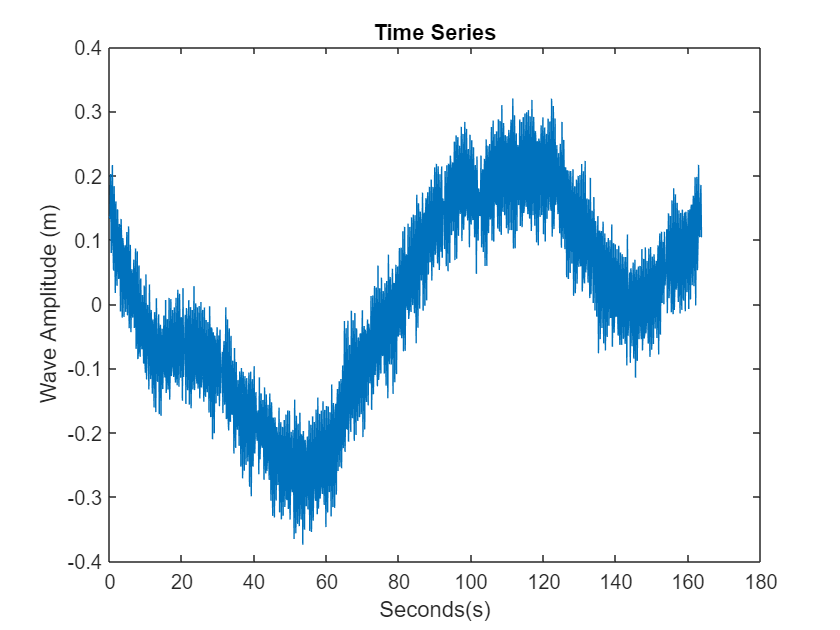

Textfile = load("SingleSegment.txt");
writematrix(Textfile, "SingleSegment.csv");
timeSeriesData = readtable("SingleSegment.csv");


N =  1024 - 1; 
timeSeriesData = (timeSeriesData{:, 1});
fs = 6.25;
time = 1/fs*(0:(N));

plot(time(1:1024), timeSeriesData(1:1024)); %only plotting the real side of the dataset 
title("Time Series");
xlabel("Seconds(s)");
ylabel("Wave Amplitude (m)");